# Quadruped robot optimization

# Step 1 - Search trajectory of leg movments

Here we are trying to teach a quadruped robot to walk using a genetic algorithm (GA).

A gait is defined as trajectory of waypoints for the reference hip and knee joint angles. These waypoints are evenly spaced in time over a predefined gait period and repeated for the duration of the simulation.

## Run previous model

clc; clear all;
typeBody = 1;
addpath(genpath('ResultOptimize18-04'))

Unrecognized function or variable 'fullpath'.

% Name of file with data
path_prev = 'trot_14_PD_ctrl_optimizedData_20Apr22_0115';
run_previous;
PlotCoM_xyz;

disp(['Main characteristics. Mean Z position: ' num2str(mean_Z) ...
       ' [m], mean velocity forward: ' num2str(mean_velocity)...
       ' [m/s], Cost Of Transport: ' num2str(CoT)])
% close all force

## Set parameters for optimization

Define the desired velocity, type of actuators and total gait time (each point is evenly spaced within this time)

clear prev_simout path_prev meanZ meanVel CoT;

robotParameters; % Paramaters of robot and simulation
typeBody = 1; % Body's type is without spine 
numPoints = 6; % Number of joint angle points
mdlName = 'QR_Unitree'; % Main model
% open_system(mdlName);

Choose type control of legs: 1 - Motor; 2 - PD control; 4 - Motion

actuatorType = 2;

Set desired velocity for optimization, [m/s]

v_des = 0.9;

Set desired mean z position, [m]

z_des = 0.3;

Period of walking gait, [s]

gait_period = 0.6;

To reduce the search space, scale the angle waypoints and solve the optimization algorithm with integer parameters. This scaling factor is from degrees to an integer.

scalingFactor = 3;

Create initial conditions to seed the previus population for optimization.

% You can fill inital population previous data 
p0 = [femur_motionFront(1:end-1),...
    tibia_motionFront(1:end-1),...
    femur_motionRear(1:end-1),...
    tibia_motionRear(1:end-1),...
    delta_gait_front, delta_gait_rear]/scalingFactor;

## Set optimization options

Compile the model to run a single simulation faster:

accelFlag = false;

Use parallel computing on multiple cores on your machine or on a cluster or cloud

parallelFlag = false;  

The options for the genetic algorithm are defined using the [`optimoptions`](https://www.mathworks.com/help/optim/ug/optim.problemdef.optimizationproblem.optimoptions.html) function.

population_size = 40;
opts = optimoptions('ga');
opts.Display = 'iter';
opts.MaxGenerations = 20;
opts.PopulationSize = population_size;
opts.PlotFcn = {@gaplotbestf, @gaplotexpectation}; 
opts.UseParallel = parallelFlag;
% opts.InitialPopulationMatrix = repmat(p0,[population_size 1]);

## Set joint angle bounds and constraints

upperBnd = [-85*ones(1,numPoints), ... % Femur Front Leg 
            110*ones(1,numPoints), ... % Tibia Front Leg 
            -85*ones(1,numPoints), ... % Femur Rear Leg 
            110*ones(1,numPoints), ... % Tibia Rear Leg 
            60*ones(1,2)] ... % Delay in percent
            /scalingFactor;
lowerBnd = [-170*ones(1,numPoints), ... % Femur Front Leg
            30*ones(1,numPoints), ... % Tibia Front Leg
            -170*ones(1,numPoints), ... % Femur Rear Leg 
            30*ones(1,numPoints), ... % Tibia Rear Leg 
            5*ones(1,2)] ... % Delay in percent
            /scalingFactor;

doSpeedupTasks;

## Run optimization

Here we use the [`ga`](https://www.mathworks.com/help/gads/ga.html) function from Global Optimization Toolbox to optimize the walking gait, with **simulateQuadrupedRobot** as the fitness function.

costFcn = @(p)simulateQuadrupedRobot(p,mdlName,scalingFactor,gait_period,v_des,actuatorType,z_des);
disp(['Running optimization. Population: ' num2str(opts.PopulationSize) ...
       ', Max Generations: ' num2str(opts.MaxGenerations)])

Running optimization. Population: 40, Max Generations: 20



Single objective optimization:
26 Variable(s)
26 Integer variable(s)

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
Vel-19171.5087 XYZ-3.1533 agr-120 pen-7254360.471
Vel-7117.6266 XYZ-3.0406 agr-362880 pen-7853275564.8195
Vel-3288974.9569 XYZ-1.0358 agr-362880 pen-1236259169909.92
Vel-115.3677 XYZ-1.3626 agr-362880 pen-57045511.3619
Vel-0.24936 XYZ-1.5137 agr-40320 pen-15218.6532
Vel-71763.2576 XYZ-1.8627 agr-5040 pen-673715406.5037
Vel-12223.0662 XYZ-3.1793 agr-720 pen-27979729.3561
Vel-94218.225 XYZ-1.5012 agr-40320 pen-5702855854.0909
Vel-2884525.5771 XYZ-1.0731 agr-40320 pen-124802725212.5867
Vel-2515274.4652 XYZ-1.0693 agr-5040 pen-13555319932.4998
Vel-20836.446 XYZ-2.463 agr-362880 pen-18622839825.542
Vel-264508.0821 XYZ-20.0007 agr-720 pen-3809041233.7223
Vel-568322.8463 XYZ-4.1451 agr-40320 pen-94982956657.0361
Vel-60313.0863 XYZ-2.5875 agr-40320 pen-6292222444.69

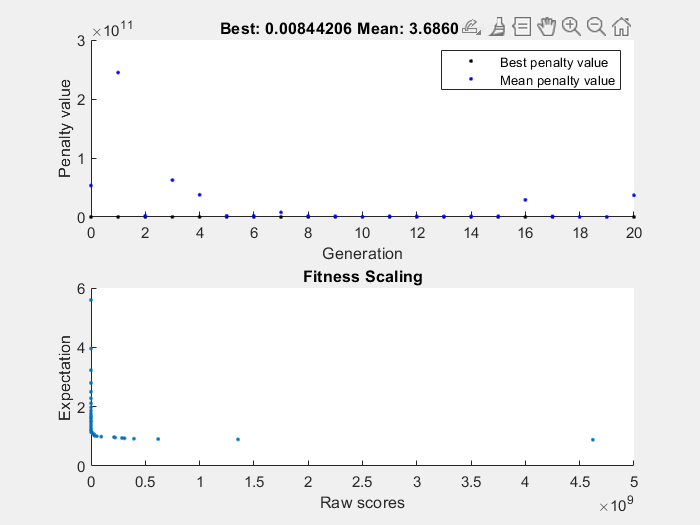

Vel-1.0941e-05 XYZ-1.0717 agr-720 pen-0.0084421
Optimization terminated: maximum number of generations exceeded.


[pFinal,reward,~,output,last_population,last_scores] = ga(costFcn,numPoints*4+2,[],[],[],[], ... 
                      lowerBnd,upperBnd,[],1:numPoints*4+2,opts);

disp(['Final reward function value: ' num2str(reward)])

Final reward function value: 0.0084421


set_param(mdlName,'SimMechanicsOpenEditorOnUpdate','on'); % On Mechanics Explorers
set_param(mdlName,'FastRestart','off'); % Off Fast Restart
delete(gcp('nocreate')); % Shutdown parallel pool

## Analyze and save results

Convert from optimization integer search space to trajectories in radians

indiv = 36;
pScaled = scalingFactor*last_population(indiv,:);%pFinal;
reward = last_scores(indiv,:);
traj_times = linspace(0,gait_period,numPoints+1);
femur_motionFront = deg2rad([pScaled(1:numPoints) pScaled(1)]);
tibia_motionFront = deg2rad([pScaled(numPoints+1:2*numPoints) pScaled(numPoints+1)]);
femur_motionRear = deg2rad([pScaled(2*numPoints+1:3*numPoints) pScaled(2*numPoints+1)]);
tibia_motionRear = deg2rad([pScaled(3*numPoints+1:4*numPoints) pScaled(3*numPoints+1)]);
delta_gait_front = pScaled(end-1);
delta_gait_rear = pScaled(end);

Evaluate the trajectory at a few points for visualization

numTrajPoints = 101;
evalTimes = linspace(0,gait_period,numTrajPoints);
[q_fr,fem_der_front,tib_der_front] = createSmoothTrajectory(femur_motionFront,tibia_motionFront,gait_period,evalTimes);
[q_rr,fem_der_rear,tib_der_rear] = createSmoothTrajectory(femur_motionRear,tibia_motionRear,gait_period,evalTimes);

Plot the resulting trajectory

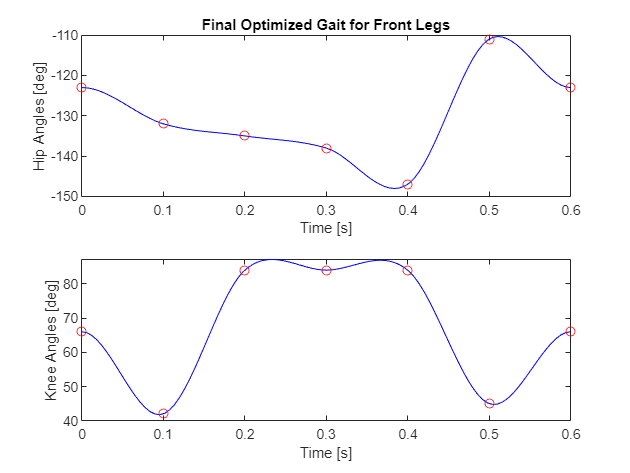

figure
subplot(2,1,1)
plot(evalTimes,rad2deg(q_fr(1,:)),'b-',traj_times,rad2deg(femur_motionFront),'ro');
title('Final Optimized Gait for Front Legs')
xlabel('Time [s]');
ylabel('Hip Angles [deg]');
subplot(2,1,2)
plot(evalTimes,rad2deg(q_fr(2,:)),'b-',traj_times,rad2deg(tibia_motionFront),'ro');
xlabel('Time [s]');
ylabel('Knee Angles [deg]');

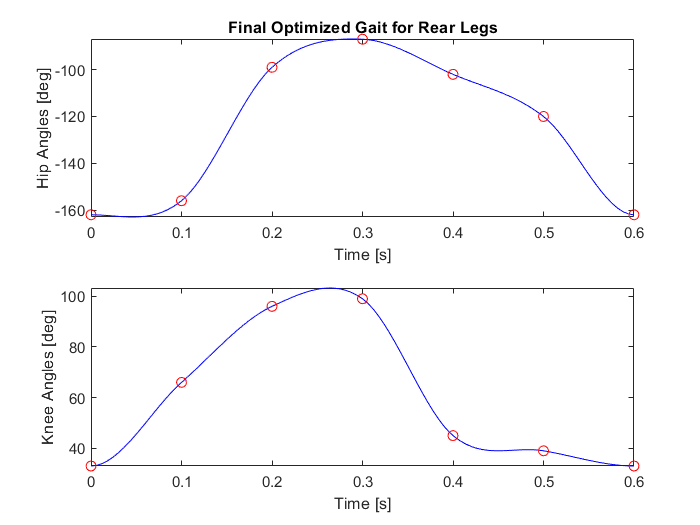

figure
subplot(2,1,1)
plot(evalTimes,rad2deg(q_rr(1,:)),'b-',traj_times,rad2deg(femur_motionRear),'ro');
title('Final Optimized Gait for Rear Legs')
xlabel('Time [s]');
ylabel('Hip Angles [deg]');
subplot(2,1,2)
plot(evalTimes,rad2deg(q_rr(2,:)),'b-',traj_times,rad2deg(tibia_motionRear),'ro');
xlabel('Time [s]');
ylabel('Knee Angles [deg]');

Save results to a timestamped MAT-file

choice_ctrl_legs;
if v_des < 0.9
    type_locomotion = 'walk';
elseif v_des >= 0.9 && v_des < 1.5
    type_locomotion = 'trot';
elseif v_des >= 1.5 
    type_locomotion = 'bouncing';
end
save_actType = actuatorType;
save_bodyType = typeBody;
strFile = '';
outFileName = ['ResultOptimize18-04/' type_locomotion '_' indiv '_' ctrl_name '_optimizedData_' datestr(now,'ddmmmyy_HHMM')];
for idx1 = 1:numel(outFileName)
    strFile = strcat(strFile,outFileName(idx1));
end
disp(strFile); % Path to the file with optimize's trajectory

ResultOptimize18-04/trot_36_PD_ctrl_optimizedData_20Apr22_0115


save(strFile,...
    'reward','gait_period','traj_times','femur_motionFront','tibia_motionFront',...
    'delta_gait_front','femur_motionRear','tibia_motionRear','delta_gait_rear',...
    'save_actType','save_bodyType');

## Simulate optimize model and plot figures

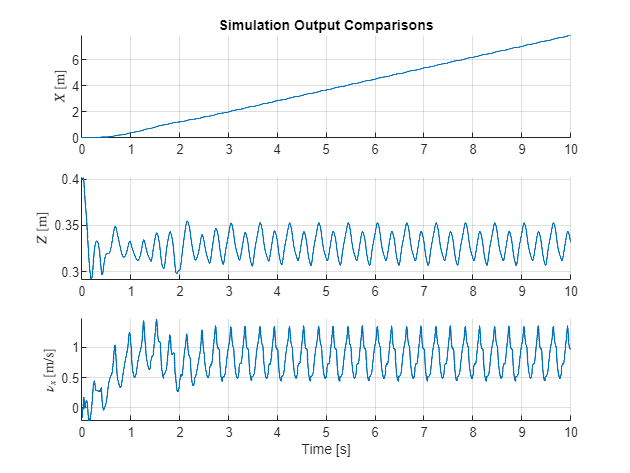

typeBody = 1;
path_prev = strFile; % Run model with previos section trajectory
run_previous;

PlotCoM_xyz;

disp(['Mean Z position: ' num2str(mean_Z) ...
       ' [m], mean velocity forward: ' num2str(mean_velocity)...
       ' [m/s], Cost Of Transport: ' num2str(CoT)])

Mean Z position: 0.32651 [m], mean velocity forward: 0.74457 [m/s], Cost Of Transport: 0.46536


## Cleanup

Close the model and, if a parallel pool was created, delete it.

close all force; % Clear figures
doCleanup = true;
if doCleanup
    bdclose(mdlName);
    if parallelFlag
        delete(gcp('nocreate'));
    end
end